# FastGapFill tutorial

**Author(s): Ines Thiele, Ronan M. T. Fleming, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Reviewer(s): **

In this tutorial, we show to identify deadend metabolites and blocked reactions as well as how to fill the "gap" caused by the deadend metabolites using fastGapFill.

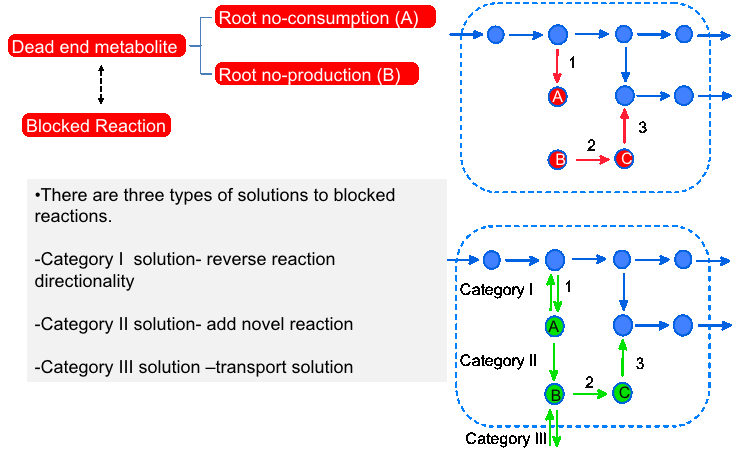

The function fastGapFill [1] identifies potential missing reactions from a model using KEGG as a reference database (as provided by fastGapFill [1], default: reaction.lst). Please note that the computed solutions needs to be manually evaluated for biological relevance. Also note that not all gaps will be filled, either due to missing mapping between model metabolite abbreviations and KEGG compound ID's (defined in 'KEGG_dictionary.xls') or due to missing matches in the reference database.

Note that the fastGapFill fills all gaps at once, eliminating the issue of combinatorics, which may be associated with other gap filling tools. However, the optimal solution is defined as being the most compact (i.e., the least number of reactions to be added) solution. In contrast, other methods have been developed that make use of other criteria, such as sequence evidence. 

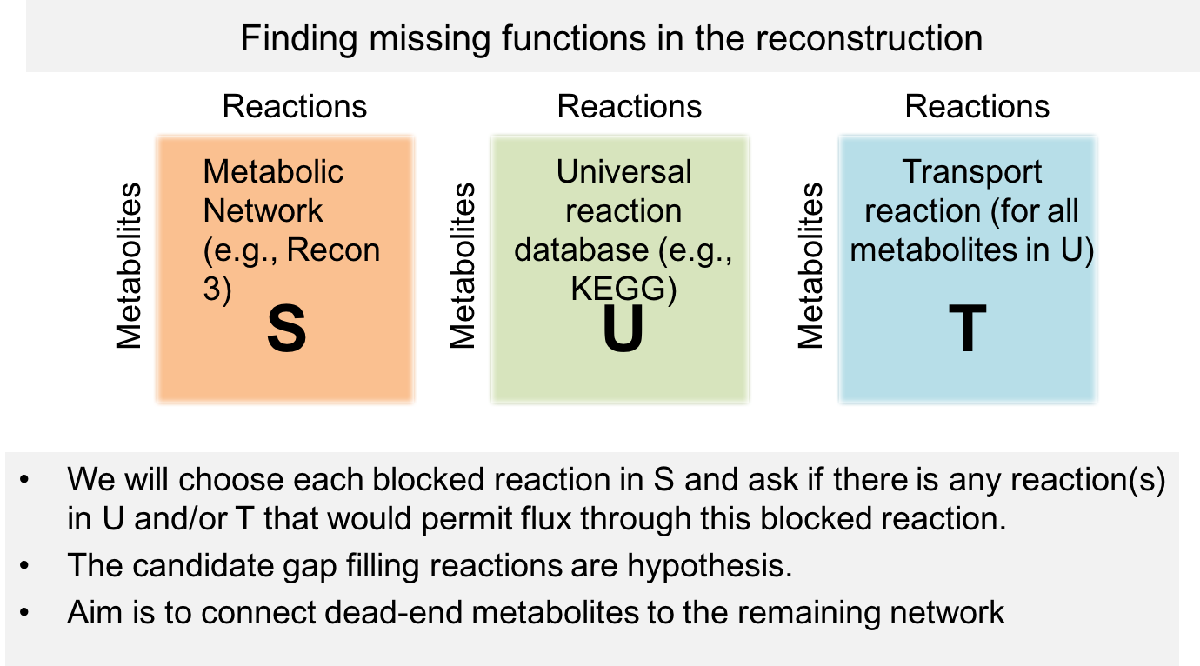

fastGapFill works on compartmentalized models. The reference database (U) will be added to each compartment, thus enabling gap filling of missing reactions in each compartment, and corresponding transport reactions connecting each metabolite in the reference database and in the reconstruction from a respective compartment with the cytosol (T).

The tutorial demonstrates the use of fastGapFill with the human metabolic reconstruction, Recon 3 [2], but it can be used with any metabolic model that is consistent with the COBRA toolbox.

Note that the solutions are not automatically categorized in this tutorial but that this needs to be done manually.

This tutorial is based on [1].

## EQUIPMENT SETUP

If necessary, initialize the cobra toolbox:

initCobraToolbox(false) % false, as we don't want to update

For solving linear programming problems in FBA analysis, certain solvers are required:

changeCobraSolver ('gurobi', 'all', 1);

This tutorial can be run with `'glpk``'` package as linear programming solver, which does not require additional instalation and configuration. However, for the analysis of large models, such as Recon 3, it is not recommended to use `'glpk``'` but rather industrial strength solvers, such as the `'gurobi'` package. 

warning off MATLAB:subscripting:noSubscriptsSpecified

## TIME REQUIREMENTS

Hours to days, depending on model size (i.e., number of intracellular compartments) and computer performance.

## PROCEDURE

Before proceeding with the simulations, the path for the model needs to be set up:

pathModel = '~/work/sbgCloud/data/models/unpublished/Recon3D_models/';
filename = '2017_04_28_Recon3d.mat';
load([pathModel, filename])
model = modelRecon3model;
clear modelRecon3model

In this tutorial, the used model is the generic model of human metabolism, the Recon 3 [2]. 

## Identification of deadend metabolites

- Detect deadend metabolites

outputMets = detectDeadEnds(model)

- print the corresponding metabolite names

DeadEnds = model.mets(outputMets)

- These metabolites are only produced or consumed in the network and the associated reactions are blocked reactions.

- Identify associated reactions:

[rxnList, rxnFormulaList] = findRxnsFromMets(model, DeadEnds)

- As you can see, these metabolites have each two reactions associated. Why are they then detected as deadend metabolites?

- Let's have a look at the lower and upper bounds of these reactions:

model.lb(find(ismember(model.rxns,rxnList)))
model.ub(find(ismember(model.rxns,rxnList)))

- The function 'detectDeadEnds' identifies all metabolites that can be only produced or consumed in the model, aka. root deadends (or 'rootGaps'). However, in some cases it may be of interest to also identify those metabolites that are produced and consumed in the network based on topology but whose reactions cannot carry flux as they are connected to reaction(s) that involve deadend metabolites (i.e., they are connected to blocked reactions).

- To identify these 'downstream' metabolites use with the option 'true':

[allGaps, rootGaps, downstreamGaps] = gapFind(model, 'true');

- The output include the root deadend metabolites ('rootGaps'), the downstream metabolites ('downstreamGaps') as well as a combined list of these two ('allGaps').

- Note that gapFind may take some computation time depending on model size. 

## Identification of blocked reactions

- Both the root and the downstream metabolites are part of reactions that cannot carry any flux (aka. blocked reactions), under the given network topology and simulation constraints.

- Run analysis for blocked reactions. The function returns a list of blocked reactions (‘BlockedReactions’).

BlockedReactions = findBlockedReaction(model)

## fastGapFill

FastGapFill allows to set different priorities for reaction types (MetabolicRxns = internal metabolic reactions in the reference database (here, KEGG), ExchangeRxns = exchange reactions, and TransportRxns = intra- and extracellular transport reactions) using the weights. The lower the weight for a reaction type, the higher is its priority. Generally, a metabolic reaction should be prioritised in a solution over transport and exchange reactions.

weights.MetabolicRxns = 0.1; % Kegg metabolic reactions
weights.ExchangeRxns = 0.5; % Exchange reactions
weights.TransportRxns = 10; % Transport reactions

In this example, the priority is given to the metabolic reactions follow by the exchange reactions and the transport reactions, because the internal reactions are better describe and annotated, but we not exclude the others.

***Hint***: The performance of algorithm is best if the weighting parameter is not 1.

**Prepare the output table with statistics.**

cnt = 1;
Stats{cnt,1} = 'Model name';cnt = cnt+1;
Stats{cnt,1} = 'Size S (original model)';cnt = cnt+1;
Stats{cnt,1} = 'Number of compartments';cnt = cnt+1;
Stats{cnt,1} = 'List of compartments';cnt = cnt+1;
Stats{cnt,1} = 'Number of blocked reactions';cnt = cnt+1;
Stats{cnt,1} = 'Number of solvable blocked reactions';cnt = cnt+1;
Stats{cnt,1} = 'Size S (flux consistent)';cnt = cnt+1;
Stats{cnt,1} = 'Size SUX (including solvable blocked reactions)';cnt = cnt+1;
Stats{cnt,1} = 'Number of added reactions (all)';cnt = cnt+1;
Stats{cnt,1} = 'Number of added metabolic reactions ';cnt = cnt+1;
Stats{cnt,1} = 'Number of added transport reactions ';cnt = cnt+1;
Stats{cnt,1} = 'Number of added exchange reactions ';cnt = cnt+1;
Stats{cnt,1} = 'Time preprocessing';cnt = cnt+1;
Stats{cnt,1} = 'Time fastGapFill';cnt = cnt+1;

In the following, we will perform the gap filling.

Initiate parameters.

col = 1;
RxnList={};
cnt = 1;

Remove constraints from exchange reactions.

EX = strmatch('EX_',model.rxns);
model.lb(EX)=-100;
model.ub(EX)=100;
clear EX

 Get basic model statistics.

Stats{cnt,2} = filename;cnt = cnt+1;
[a,b] = size(model.S);
Stats{cnt,2} = strcat(num2str(a),'x',num2str(b));cnt = cnt+1;

 List of compartments in the model that will be considered during the gap filling.

[tok,rem] = strtok(model.mets,'\[');
rem = unique(rem);
Stats{cnt,2} = num2str(length(rem));cnt = cnt+1;
Rem = rem{1};
for j = 2:length(rem)
    Rem = strcat(Rem,',',rem{j});
end
Stats{cnt,2} = Rem;cnt = cnt+1;
clear Rem tok rem;

## Prepare fastGapFill.

Here, we are going to use the function prepareFastGapFill. This function creates the new model variable (consistModel), which contains the reconstruction (S in the figure), in which the reference database (U) and the transport reactions (T) have been added to each compartment. Subsequently, all reactions that cannot carry any flux in this super-reconstruction will be removed. Note that this step is time consuming.

tic; [consistModel,consistMatricesSUX,BlockedRxns] = prepareFastGapFill(model);
tpre=toc;

- **consistModel** – Flux consistent subnetwork of the input model

- **consistMatricesSUX** – Flux consistent *SUX* matrix, which contains the flux consistent *S* matrix (model), the universal database placed in all cellular compartments along with transport reactions for each metabolite from cytosol to compartment and exchange reactions for all extracellular metabolites.

- **BlockedRxns** – Blocked reactions in model.

Add on more statistics to the table. Here, we will report how many gaps cannot be filled at all in the starting reconstruction.

Stats{cnt,2} = num2str(length(BlockedRxns.allRxns));cnt = cnt+1;
Stats{cnt,2} = num2str(length(BlockedRxns.solvableRxns));cnt = cnt+1;
[a,b] = size(consistModel.S);
Stats{cnt,2} = strcat(num2str(a),'x',num2str(b));cnt = cnt+1;
[a,b] = size(consistMatricesSUX.S);
Stats{cnt,2} = strcat(num2str(a),'x',num2str(b));cnt = cnt+1;

## Perform fastGapsFill. 

Now our model is ready to be run by the fastGapFill function. The main aim of this function is to find the most compact set of reactions, i.e., exchange, transport, and metabolic reactions from the UX matrix to be added to the input model to close the models in the gaps.

The variable epsilon defines effectively the minimum flux through a reactions that should be achieved when adding the reactions. Please refer to [3] for more details on epsilon and its use.

Note this step is time-consuming.

epsilon = 1e-4;
tic; [AddedRxns] = fastGapFill(consistMatricesSUX,epsilon, weights);
tgap=toc;
Stats{cnt,i+1} = num2str(length(AddedRxns.rxns));cnt = cnt+1;

## Postprocessing of results

Here, we assign  generalized functions to the output from *fastGapFill* (e.g., ‘Metabolic reaction’, ‘Transport reaction’, ‘Exchange reaction’). It also provides basic statistics for the solution. One can use the option ‘IdentifyPW’ to compute for each solved blocked reaction a flux vector, such that the flux through this reaction is maximized while the sum of all fluxes is minimized. This analysis can be helpful to put the solution reactions into the network context.

IdentifyPW = 0;
[AddedRxnsExtended] = postProcessGapFillSolutions(AddedRxns,model,BlockedRxns);
clear AddedRxns;

- **AddedRxnsExtended**  is a structure containing the information present in *AddedRxns* along with the statistics and if desired pathways containing the flux vectors.

Add further statistics about computed solutions to the Stats table.

Stats{cnt,i+1} = num2str(AddedRxnsExtended.Stats.metabolicSol);cnt = cnt+1;
Stats{cnt,i+1} = num2str(AddedRxnsExtended.Stats.transportSol);cnt = cnt+1;
Stats{cnt,i+1} = num2str(AddedRxnsExtended.Stats.exchangeSol);cnt = cnt+1;

Stats{cnt,i+1} = num2str(tpre);cnt = cnt+1;
Stats{cnt,i+1} = num2str(tgap);cnt = cnt+1;
clear a b

    Generate a reaction list

RxnList{1,col}=filename;RxnList(2:length(AddedRxnsExtended.rxns)+1,col) = AddedRxnsExtended.rxns; col = col + 1;
RxnList{1,col}=filename;RxnList(2:length(AddedRxnsExtended.rxns)+1,col) = AddedRxnsExtended.rxnFormula; col = col + 1;
RxnList{1,col}=filename;RxnList(2:length(AddedRxnsExtended.rxns)+1,col) = AddedRxnsExtended.subSystem; col = col + 1;

clear AddedRxnsExtended tgap tpre j BlockedRxns i cnt consistM*

## Analysis of results

Now, we are going analyze  the candidate gap filling reactions, contained in 'RxnList'.The first column correspond to the name of the reaction in the model, the second column correspond to the reactions and the last column give the compartment of the reactions.

RxnList

Now, we are going to identify the deadend metabolites, for this we are going to use the function detectDeadEnds, which returns the indices of all deadend metabolites.

metid = detectDeadEnds(model,false);

Print the metabolite abbreviations and metabolite names on the screen.

horzcat(model.mets(metid),model.metNames(metid))

## Trouble shooting

***Error***: "Combining Remaining Genetic Information: Reference to non-existent field 'rules'."

***Solution***: "Your model structure does not contain the rules field. The rules field specifies which genes encode for the reactions. You could create an array of the same length as the number of reactions in your model and empty fields."

***Error***: " I have downloaded the files and I am using the gurobi5 solver. When I am trying to run one of theirs runGapFill_example to check correct setup, this is what I am experiencing..

>> runGapFill_example

|J|=386  Undefined function 'cplexlp' for input arguments of type 'double'."

***Solution***: "Fastgapfill requires ibm cplx to be installed. Academic licenses are free."

## References

[1] fastGapFill.

[2] Brunk et al, Recon 3D, submitted.

[3] fastCore